### Problem 1

**Necessary Constants: **

R = .99; % Reflectance is 99%, and we assume R1 = R2
L = 250*10^-6; % Mirror separation is 250 microns
n = 1.45; % Refractive index of resonator material is 1.45
c = 3*10^8; % Speed of light in vacuum
lambda = (1.5*10^-6):(1*10^-12):(1.52*10^-6);  
k = (2*pi*n)./lambda;
f = c./(lambda); 


**Part a** 

The phase shift undergone by light in the cavity is given by: $-\phi =\textrm{kL}\;=\beta L\;=\;2\pi \frac{n}{\lambda }L$

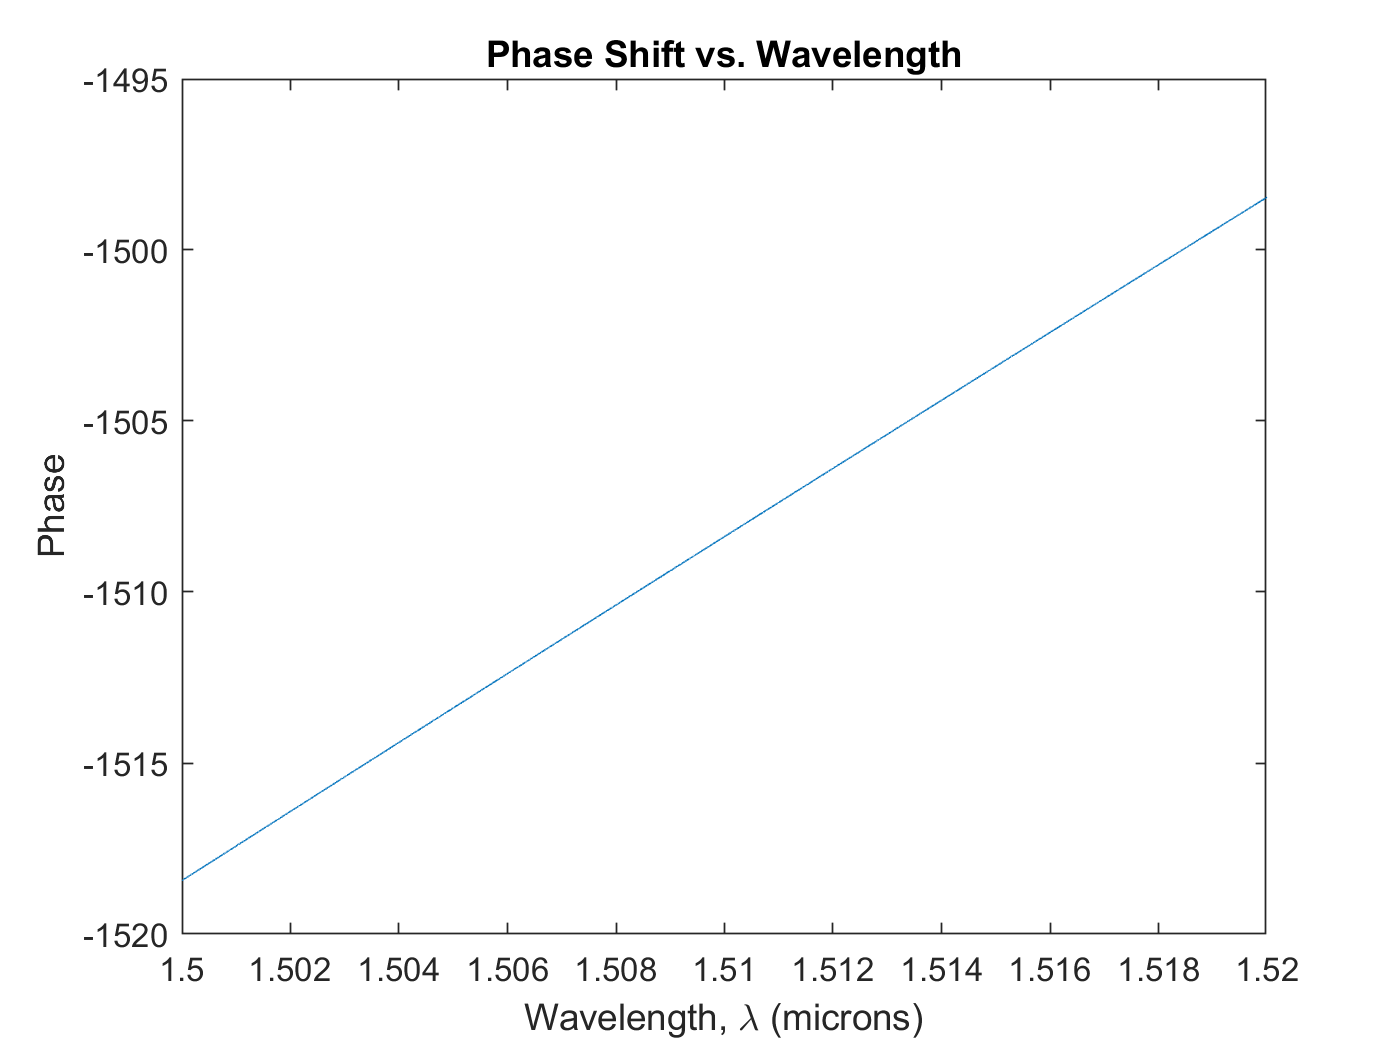

phase = -k*L;
plot(lambda*10^6,phase)
xlabel('Wavelength, \lambda (microns)')
ylabel('Phase')
title('Phase Shift vs. Wavelength')

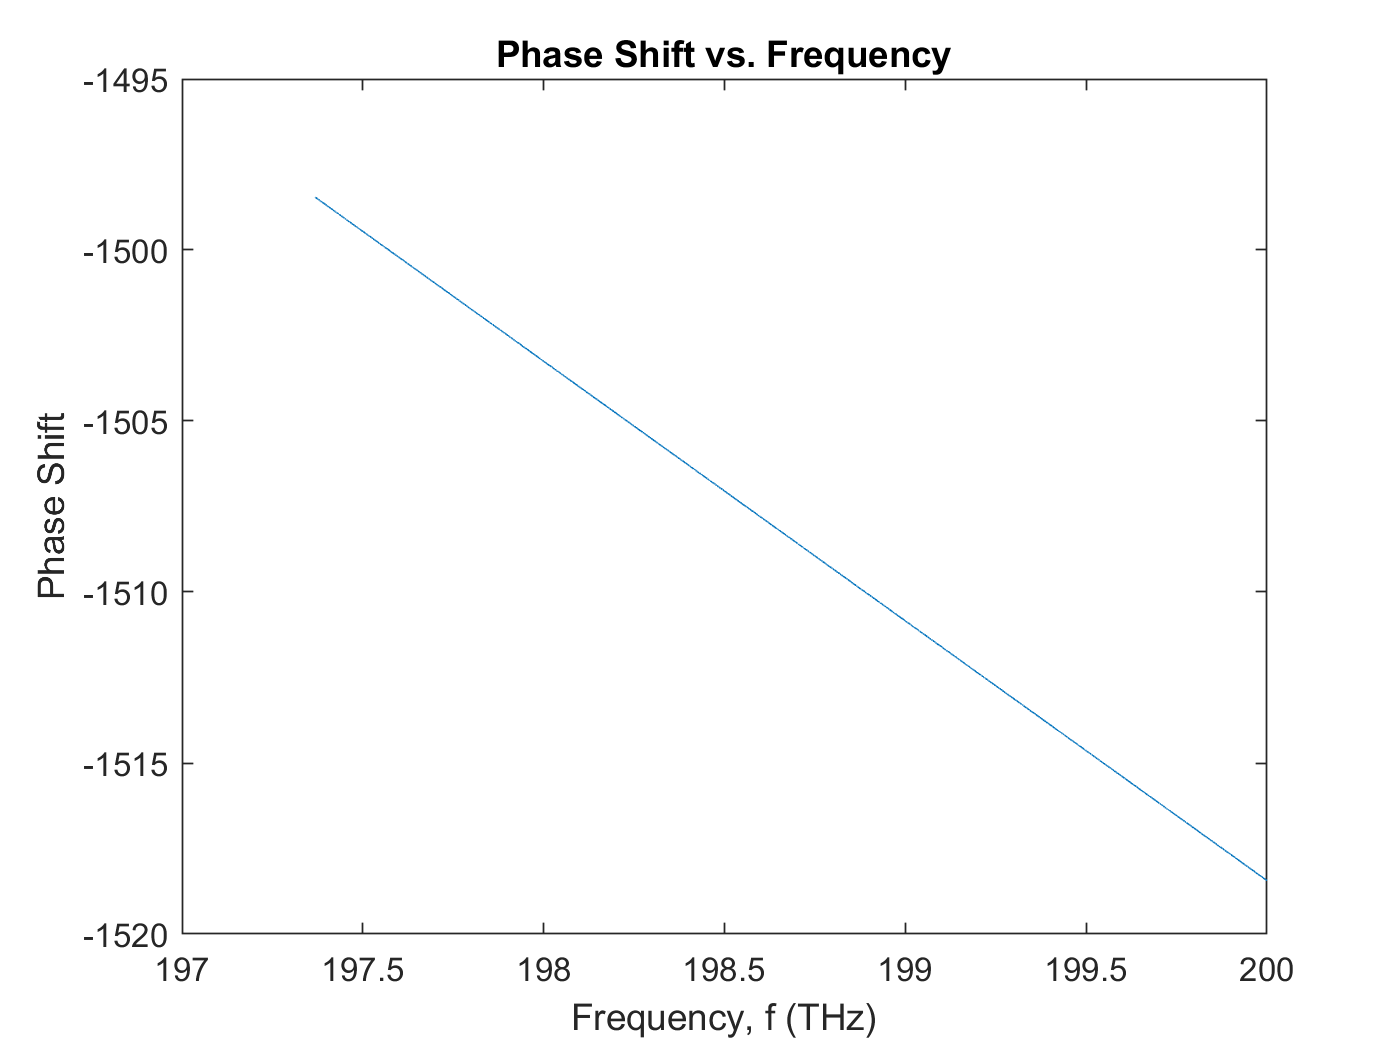

plot(f*10^-12,phase)
xlabel('Frequency, f (THz)')
ylabel('Phase Shift')
title('Phase Shift vs. Frequency')

**Part b)**

Cavity finesse is given by: $F=\pi \frac{R^{\frac{1}{2}} }{1-R}$

F = pi*sqrt(R)/(1-R)

F = 312.5845

**Part c) **

The free spectral range, $v_f$, is given by: 


$$v_f =\frac{c}{2nL}$$


vf = c/2*n*L

vf = 54375

**Part d) **

The spectral width, $\delta v_m$, is given by: 


$$\delta v_m =\frac{v_f }{F}$$


dvm = vf/F

dvm = 173.9530

**Part e)**

To determine the mode number at 1550 nm, the following equation is used: 


$$m=2\frac{\textrm{nL}}{\lambda }$$


m = 2*n*L/(1550*10^-9)

m = 467.7419

**Part f) **

The quality factor, Q, at the mode number is given by: 


$$Q=\textrm{mF}$$


Q = m*F

Q = 1.4621e+05

**Part g) **

The intensity spectrum is given by: 


$$I=\frac{I_0 }{{\left(1-R\right)}^2 +4R{\mathrm{sin}}^2 \left(\mathrm{kL}\right)}$$


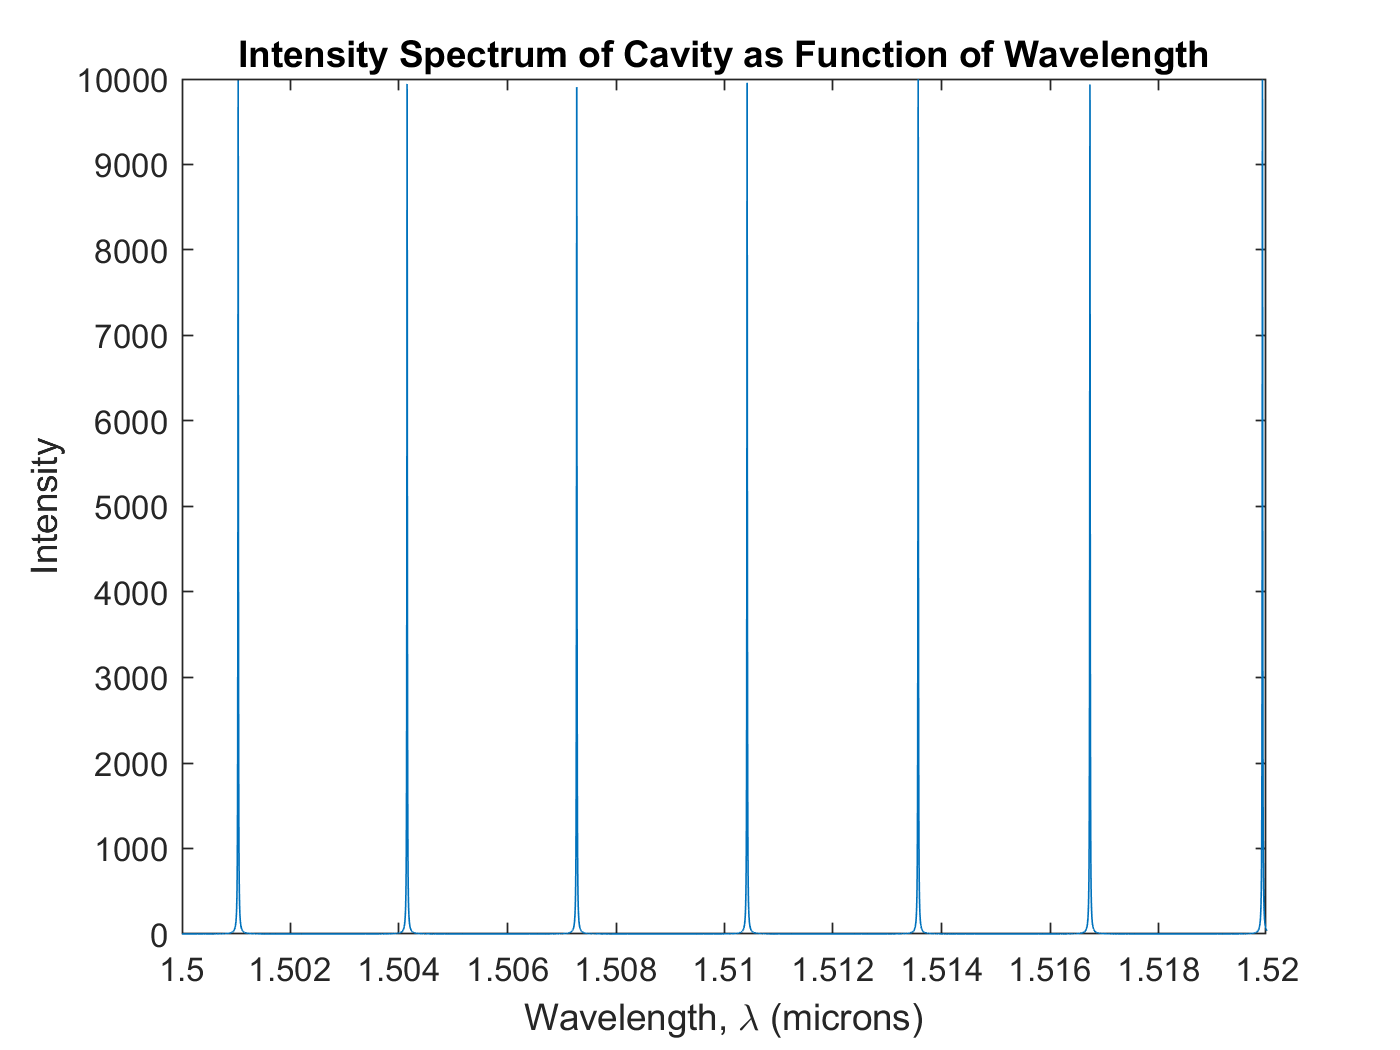

I = 1./((1-R).^2 + 4*R*(sin(k*L)).^2);
plot(lambda*10^6,I)
xlabel('Wavelength, \lambda (microns)')
ylabel('Intensity')
title('Intensity Spectrum of Cavity as Function of Wavelength')

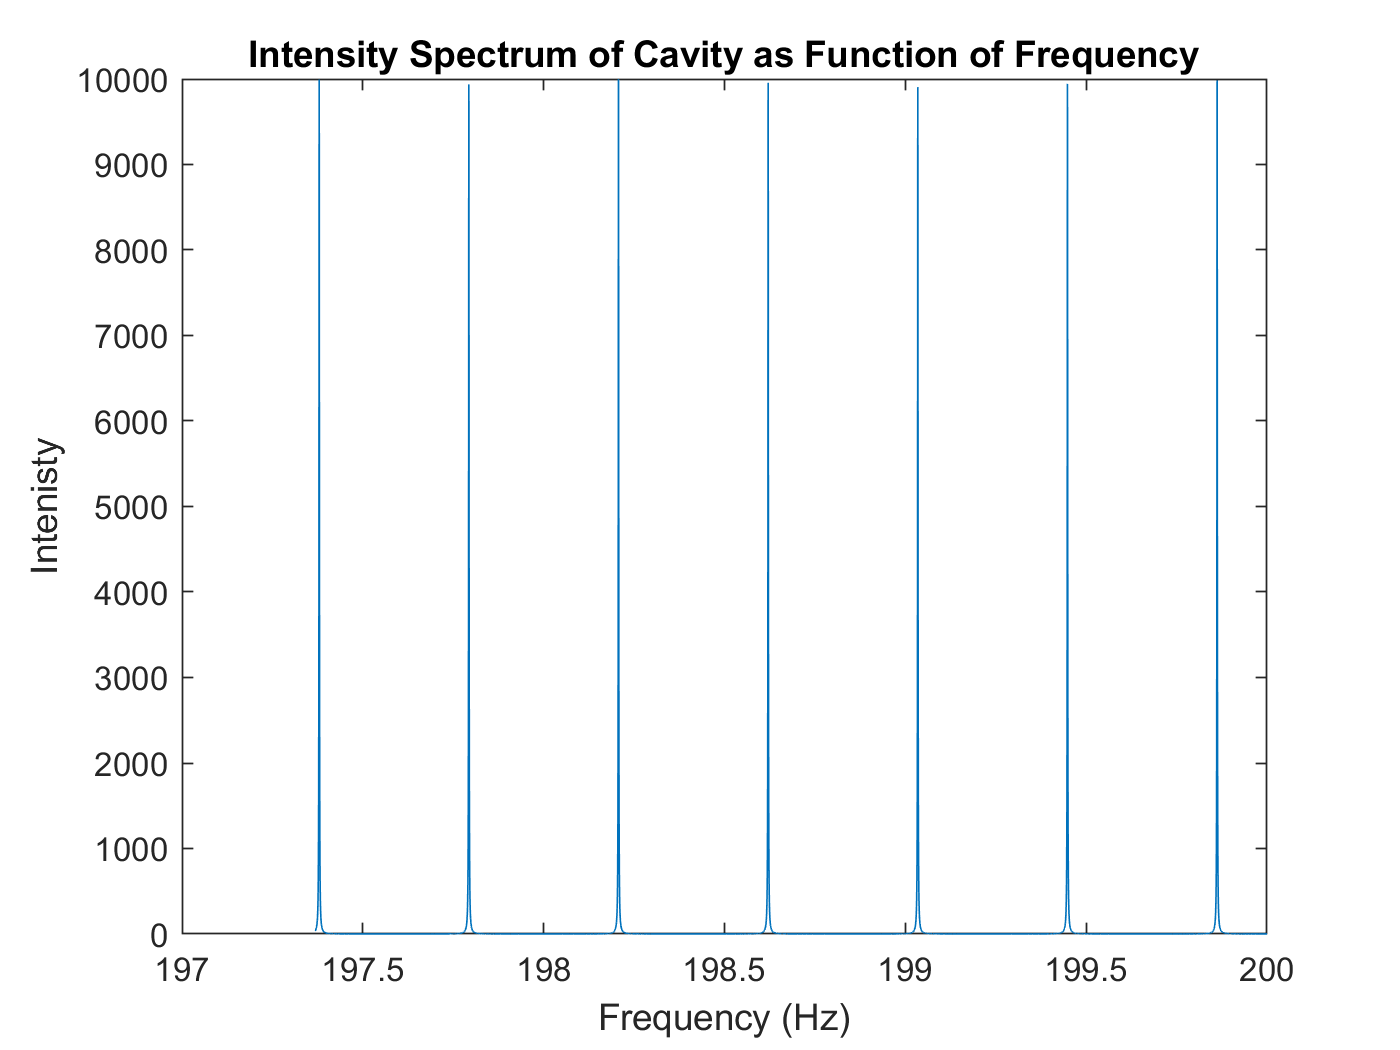

plot(f*10^-12,I)
xlabel('Frequency (Hz)')
ylabel('Intenisty')
title('Intensity Spectrum of Cavity as Function of Frequency')

**Part h)**

The inverse fourier transform of the spectrum previously calculated is given by the 'ifftshift' function, which applies a zero-frequency shift to the signal undergoing transformation

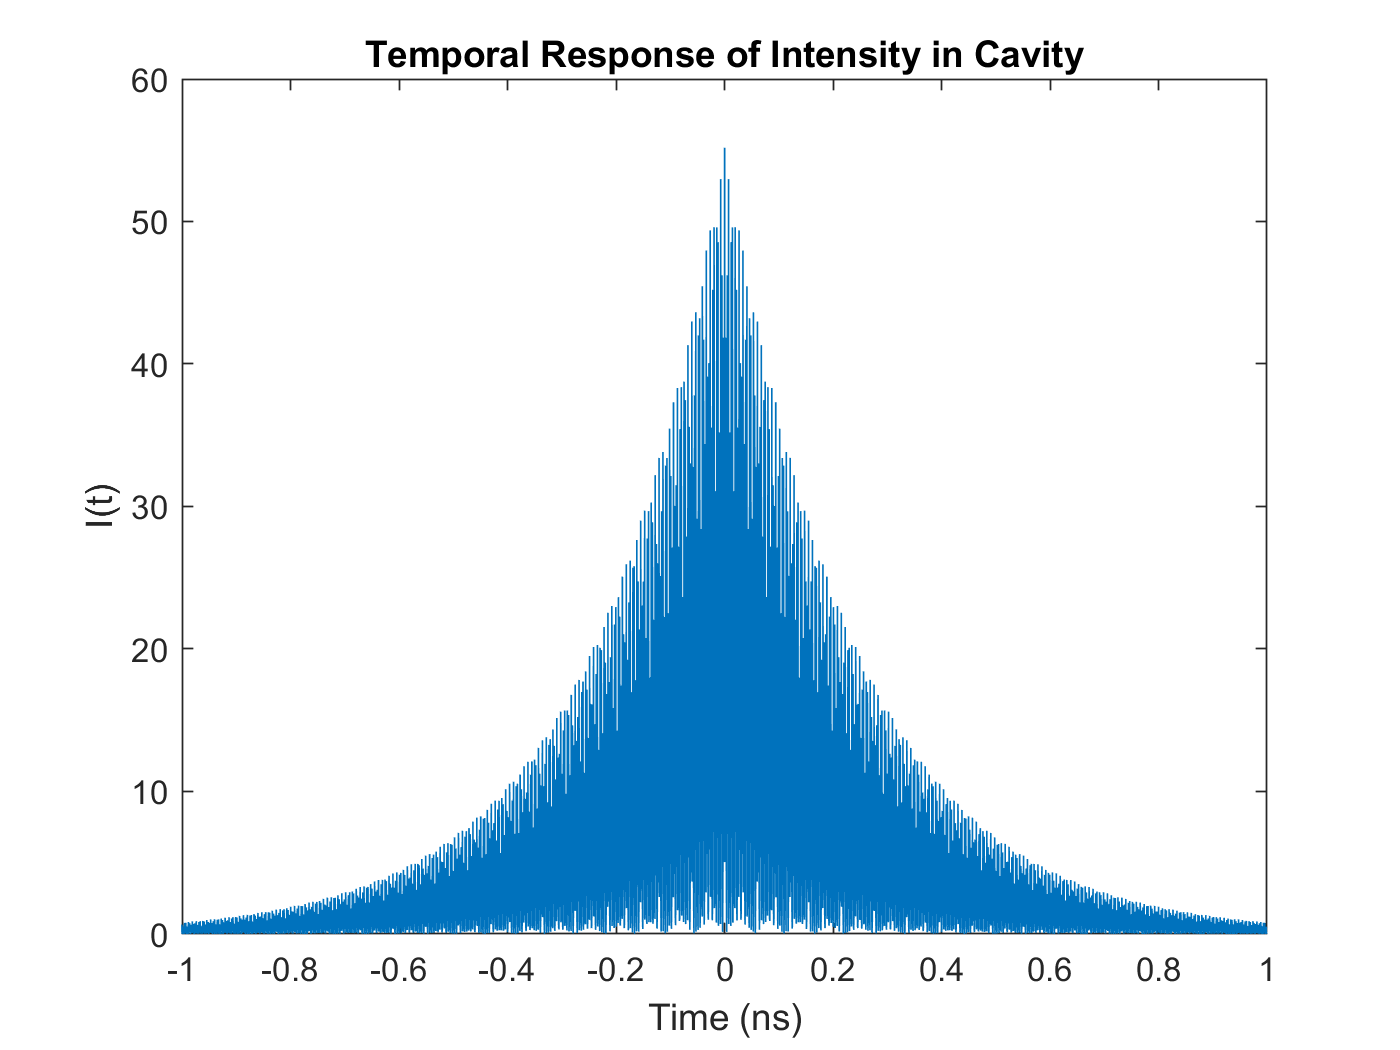

dlambda = 10^-13;
mid_lambda = 1510*10^-9;
df = (dlambda*c)/(1510*10^-9)^2;
f_sample = c/(min(lambda)) - c/(max(lambda));
fn  = -.5*f_sample:df:.5*f_sample; 
fn = fn + c/(mid_lambda);
t = -.5/df:1/f_sample:.5/df;
I_f = interp1(f,I,fn,'linear','extrap');
I_t = abs(ifftshift(ifft(I_f)));
plot(t*10^9,I_t);
xlim([-1,1])
xlabel('Time (ns)')
ylabel('I(t)')
title('Temporal Response of Intensity in Cavity')

 *The temporal response above demonstrates that the energy present in an optical cavity decays with time, which can be explained by mirror reflectivity.  The fact that R is .99, not 1.0, implies that 1% of the energy is lost every instance the path makes contact with the cavity.  Given the speeds at which photons are traveling in the cavity, the round trip time is small - consequently, the overall time necessary for the energy (thus intensity) in the cavity to decay to 0, effectively, is not long. 

**Part i)**

To determine the cavity lifetime, the round-trip time must be calculated: $\tau_{\textrm{rt}} =2\frac{\textrm{nL}}{c}$ .  Then, the photon lifetime is given by: $\tau_{\textrm{ph}} =\frac{\tau_{\textrm{rt}} }{\left(1-R_1 R_2 \right)}=\frac{\tau_{\textrm{rt}} }{\left(1-R^2 \right)}$, since $R_1 =R_2 =R$

round_trip = (2*n*L)/c;
photon_lifetime = round_trip/(1-R^2);

**Part j)**

The ratio of the photon lifetime to cavity roundtrip is: $\frac{\tau_{\textrm{ph}} }{\tau_{\textrm{rt}} }=\frac{1}{\left(1-R^2 \right)}$.  This is clearly a function of the mirror reflectivity, which makes sense.  The reflectivity determines the percentage of light intensity that remains in the cavity (reflected).  As this value increases, energy in the cavity will decay at a slower rate, which increases the photon lifetime and thus the ratio of photon lifetime to cavity roundtrip. 

#### Problem 2

**Necessary constants: **

To determine $\beta_0 \;\textrm{and}\;\beta_1 ,$ the following equations are used: 


$$\beta_0 =2\pi \frac{n}{\lambda_0 }=k_0$$



$$\beta_1 =\frac{1}{c}\left(n+\omega \frac{\textrm{dn}}{d\omega }\right)=\frac{n_g }{c}=\frac{1}{v_g }$$


lambda0 = 1510*10^-9; % Reference wavelength
f0 = c/lambda0; % Reference frequency
beta_0 = (2*pi*n)/lambda0;
beta_1 = n/c;
beta_2 = -2*10^-26; % sec^2/m, for standard single-mode fiber
beta_3 = 1*10^-40; % sec^3/m, for standard single-mode fiber
f = c./lambda;

**Part a)**

The phase is now non-constant, given by a taylor series expansion as shown below: 


$$\phi \left(\omega \right)=\beta_0 L+\beta_1 L\left(\omega -\omega_0 \right)+\frac{\beta_2 }{2}{L\left(\omega -\omega_0 \right)}^2 +\frac{\beta_3 }{3}{L\left(\omega -\omega_0 \right)}^3 =\phi_0 +\phi_1 +\phi_2 +\phi_3$$


*Although angular frequency is used in the equation above, the equations obviously still hold upon conversion to Hz.

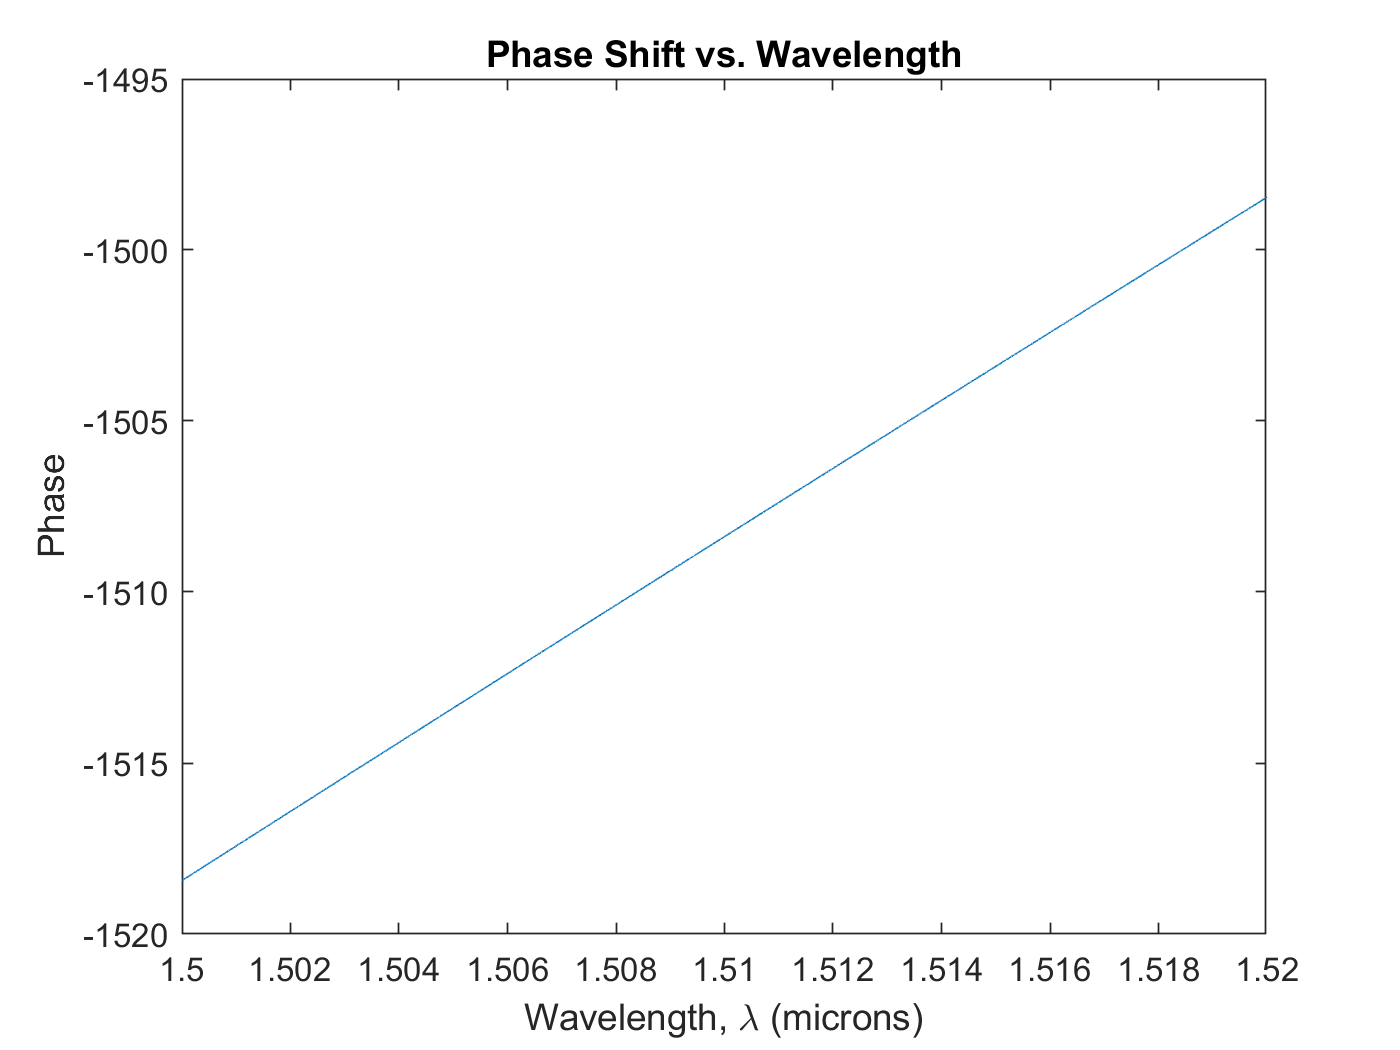

phase = -((beta_0*L) + (beta_1*L)*(2*pi*(f-f0)) + (beta_2*L/2)*(2*pi*(f-f0)).^2 + (beta_3*L/3)*(2*pi*(f-f0)).^3);
plot(lambda*10^6,phase);
xlabel('Wavelength, \lambda (microns)')
ylabel('Phase')
title('Phase Shift vs. Wavelength')

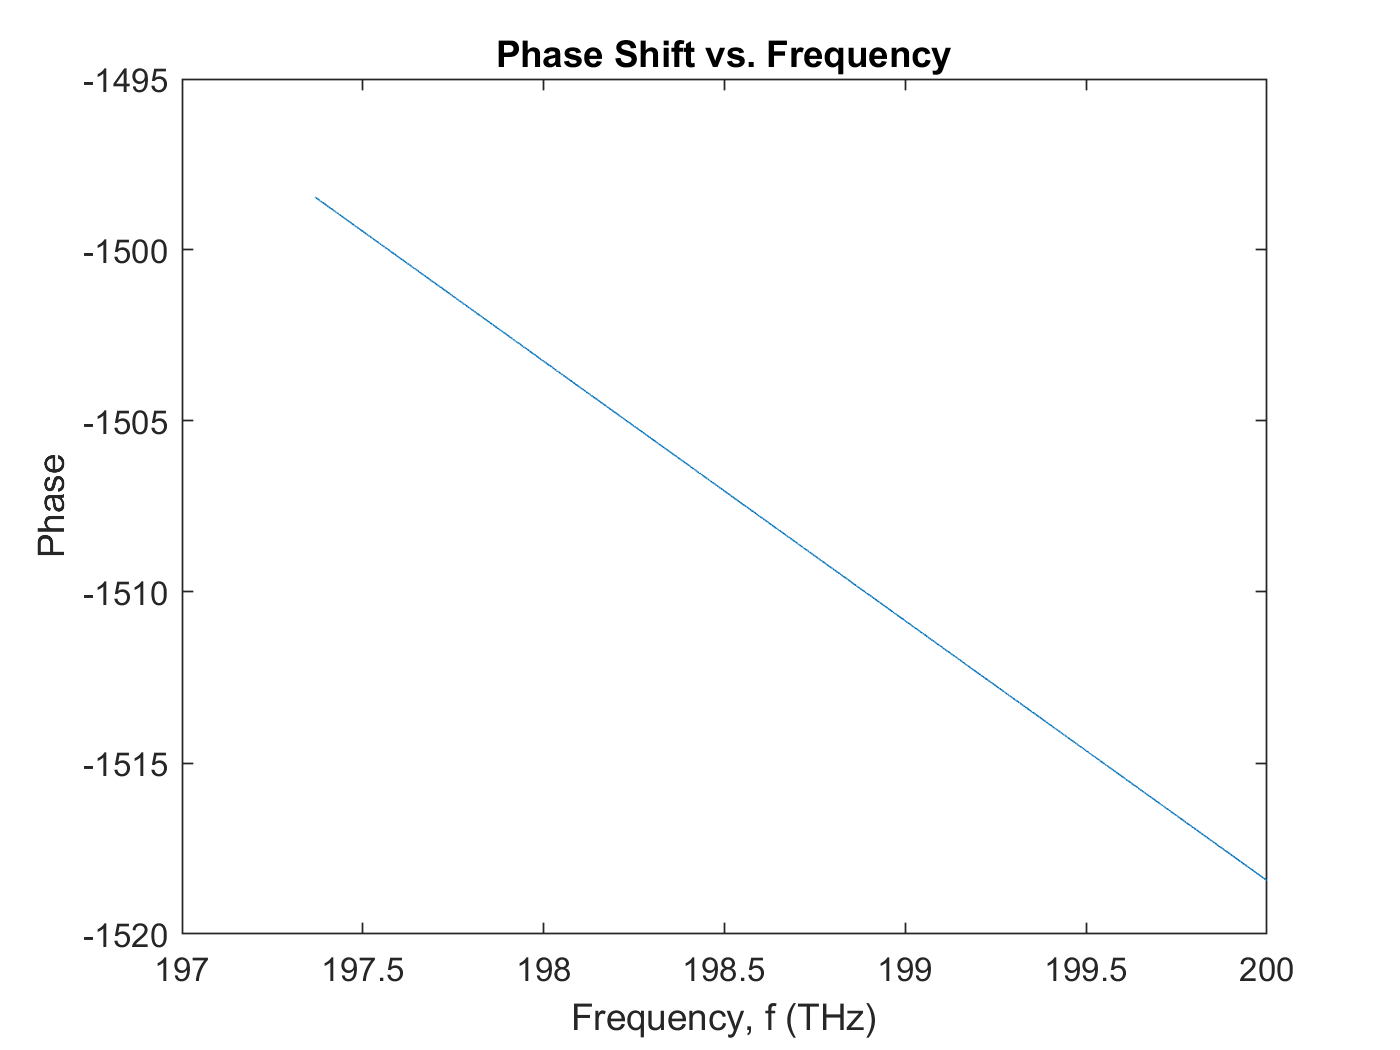

plot(f*10^-12,phase);
xlabel('Frequency, f (THz)')
ylabel('Phase')
title('Phase Shift vs. Frequency')

**Part b)**

The group delay is denoted by $\tau$, calculated via the relation: $\tau =\frac{d\phi }{d\omega }$

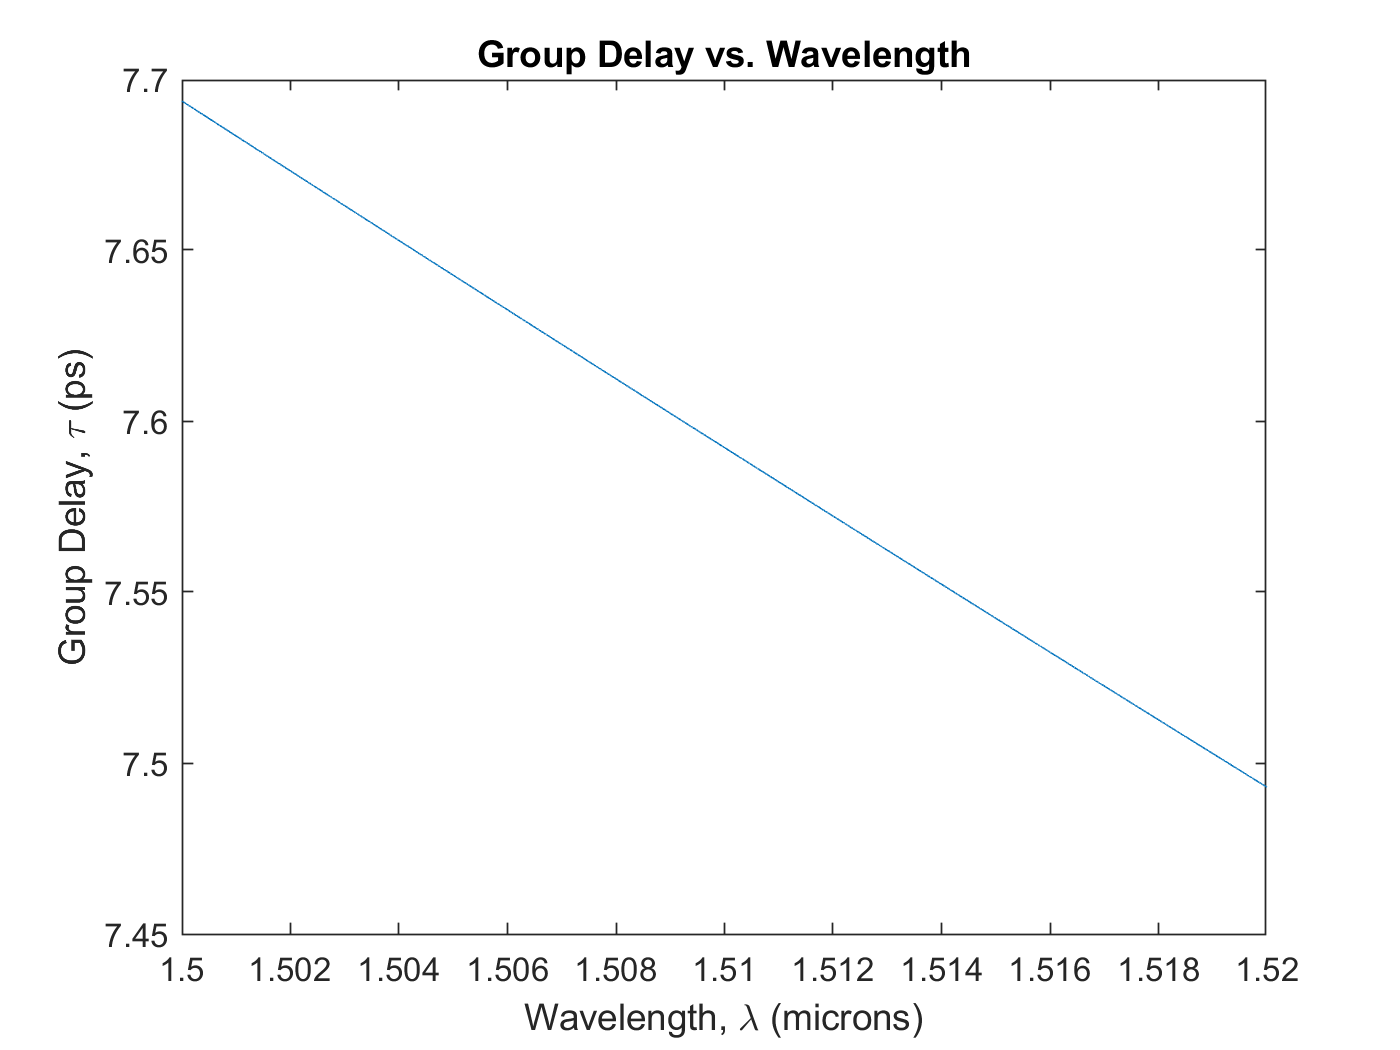

df = (max(f)-min(f))/length(f); % df, or difference of frequency terms (taken over the length)
delay = diff(phase)/df; % Derivative of phase with respect to frequency
plot(lambda(1,1:20000)*10^6,delay*10^12);
xlabel('Wavelength, \lambda (microns)')
ylabel('Group Delay, \tau (ps)')
title('Group Delay vs. Wavelength')

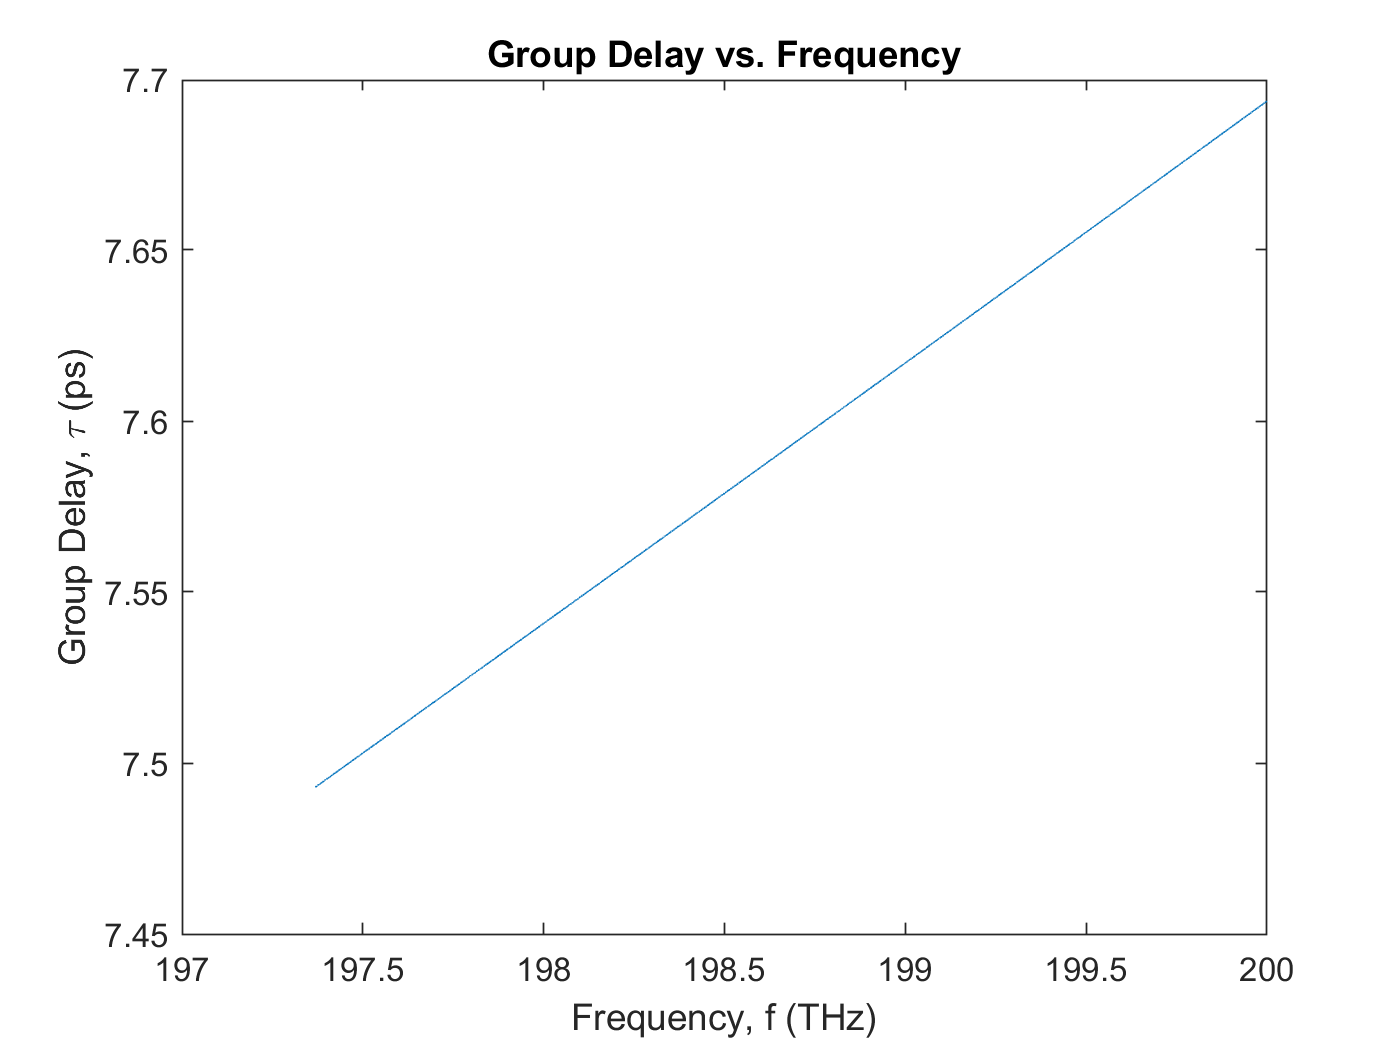

plot(f(1,1:20000)*10^-12,delay*10^12);
xlabel('Frequency, f (THz)')
ylabel('Group Delay, \tau (ps)')
title('Group Delay vs. Frequency')

**Part c) **

The four phase terms are given by the following relations: 


$$\begin{array}{l}
\phi_0 =\beta_0 L\\
\phi_1 =\beta_1 L\left(\omega_{\max } -\omega_0 \right)=\beta_1 L\left(2\pi \left(f_{\max } -f_0 \right)\right)\\
\phi_2 =\frac{\beta_2 }{2}{L\left(\omega_{\max } -\omega_0 \right)}^2 =\beta_2 {L\left(2\pi \left(f_{\max } -f_0 \right)\right)}^2 \\
\phi_3 =\frac{\beta_3 }{6}{L\left(\omega_{\max } -\omega_0 \right)}^3 =\frac{\beta_3 }{6}{L\left(2\pi \left(f_{\max } -f_0 \right)\right)}^3 
\end{array}$$


fmax = c/(1500*10^-9);
f0 = c/(1510*10^-9);
f_calc = fmax - f0;
phase_0 = beta_0*L

phase_0 = 1.5084e+03

phase_1 = beta_1*L*(2*pi*f_calc)

phase_1 = 10.0559

phase_2 = (beta_2/2)*L*(2*pi*f_calc)^2

phase_2 = -1.7314e-04

phase_3 = (beta_3/6)*L*(2*pi*f_calc)^3

phase_3 = 2.4015e-06

**Part d) **

The intensity spectrum is given by: 

$I=\frac{I_0 }{{\left(1-R\right)}^2 +4R\sin^2 \left(\beta L\right)}$ , where $\beta$ is the phase per unit length and represented by the relation: $\beta =\beta_0 +\beta_1 L\left(\omega -\omega_0 \right)+\frac{\beta_2 }{2}{L\left(\omega -\omega_0 \right)}^2 +\frac{\beta_3 }{6}{L\left(\omega -\omega_0 \right)}^3$

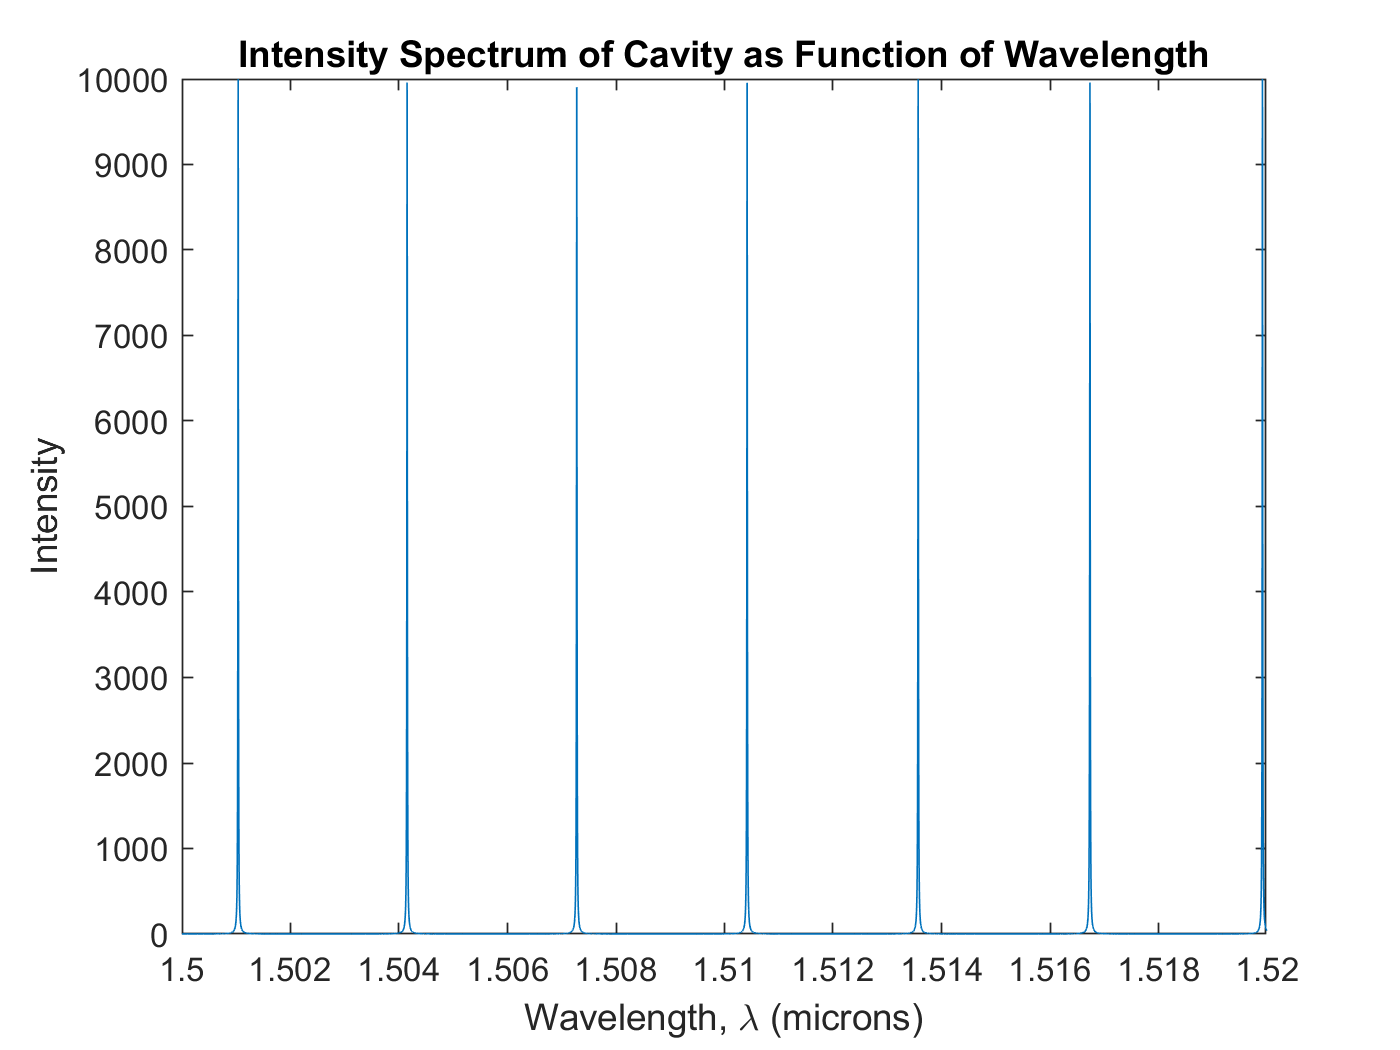

beta = beta_0 + beta_1*(2*pi*(f-f0)) + (beta_2/2)*(2*pi*(f-f0)).^2 + (beta_3/6)*(2*pi*(f-f0)).^3;
I = 1./((1-R).^2 + 4*R*(sin(beta*L)).^2);
plot(lambda*10^6,I)
xlabel('Wavelength, \lambda (microns)')
ylabel('Intensity')
title('Intensity Spectrum of Cavity as Function of Wavelength')

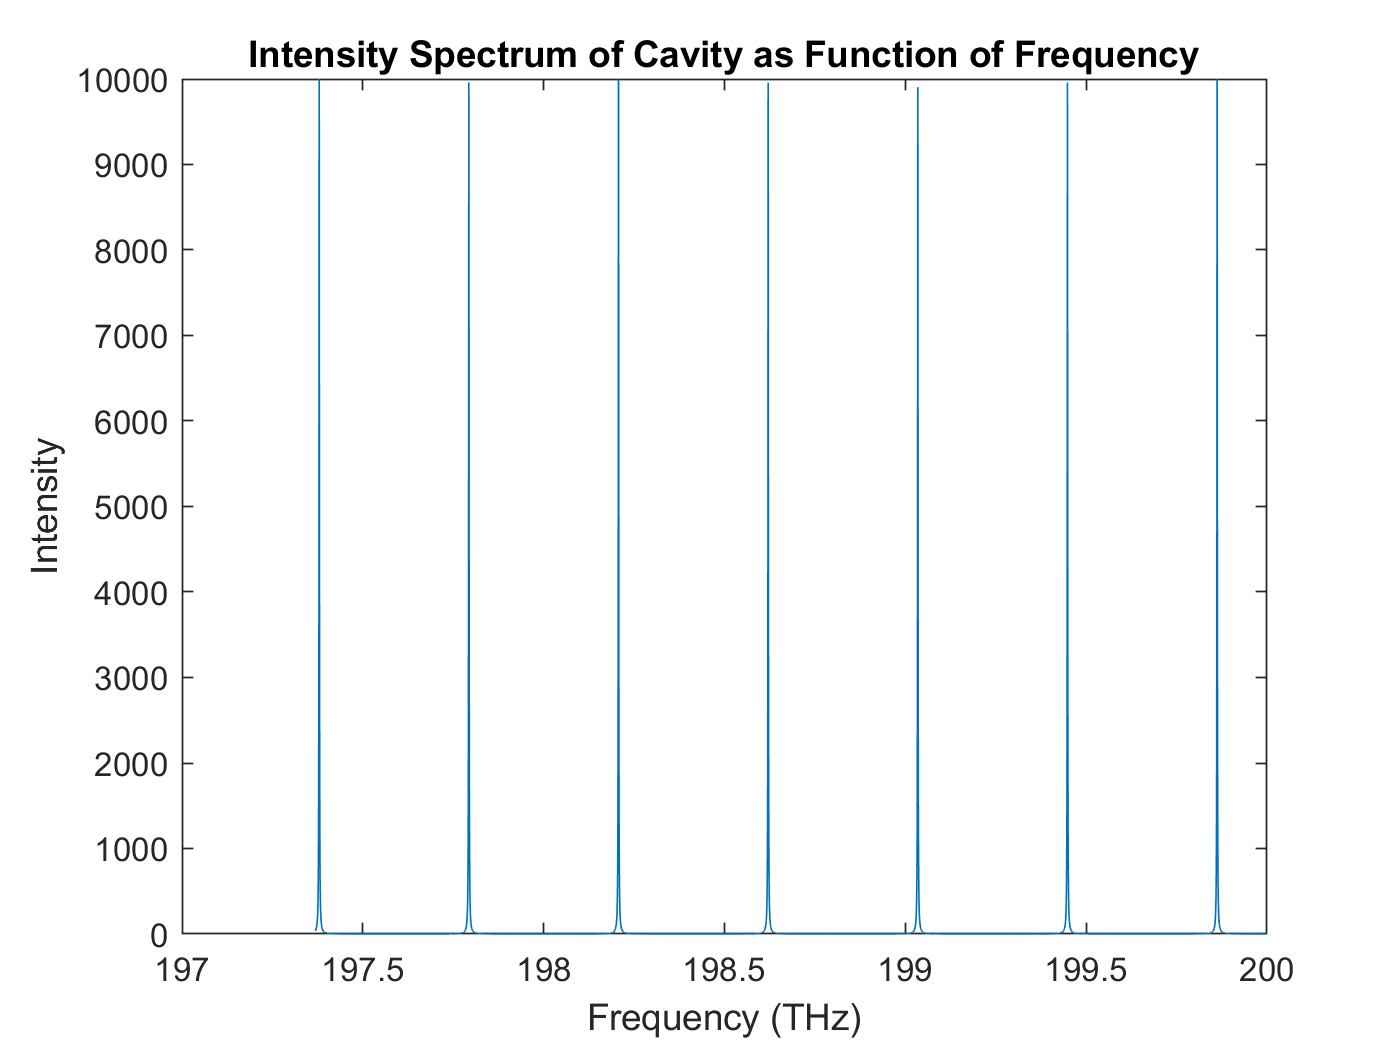

plot(f*10^-12,I)
xlabel('Frequency (THz)')
ylabel('Intensity')
title('Intensity Spectrum of Cavity as Function of Frequency')

**Part e) **

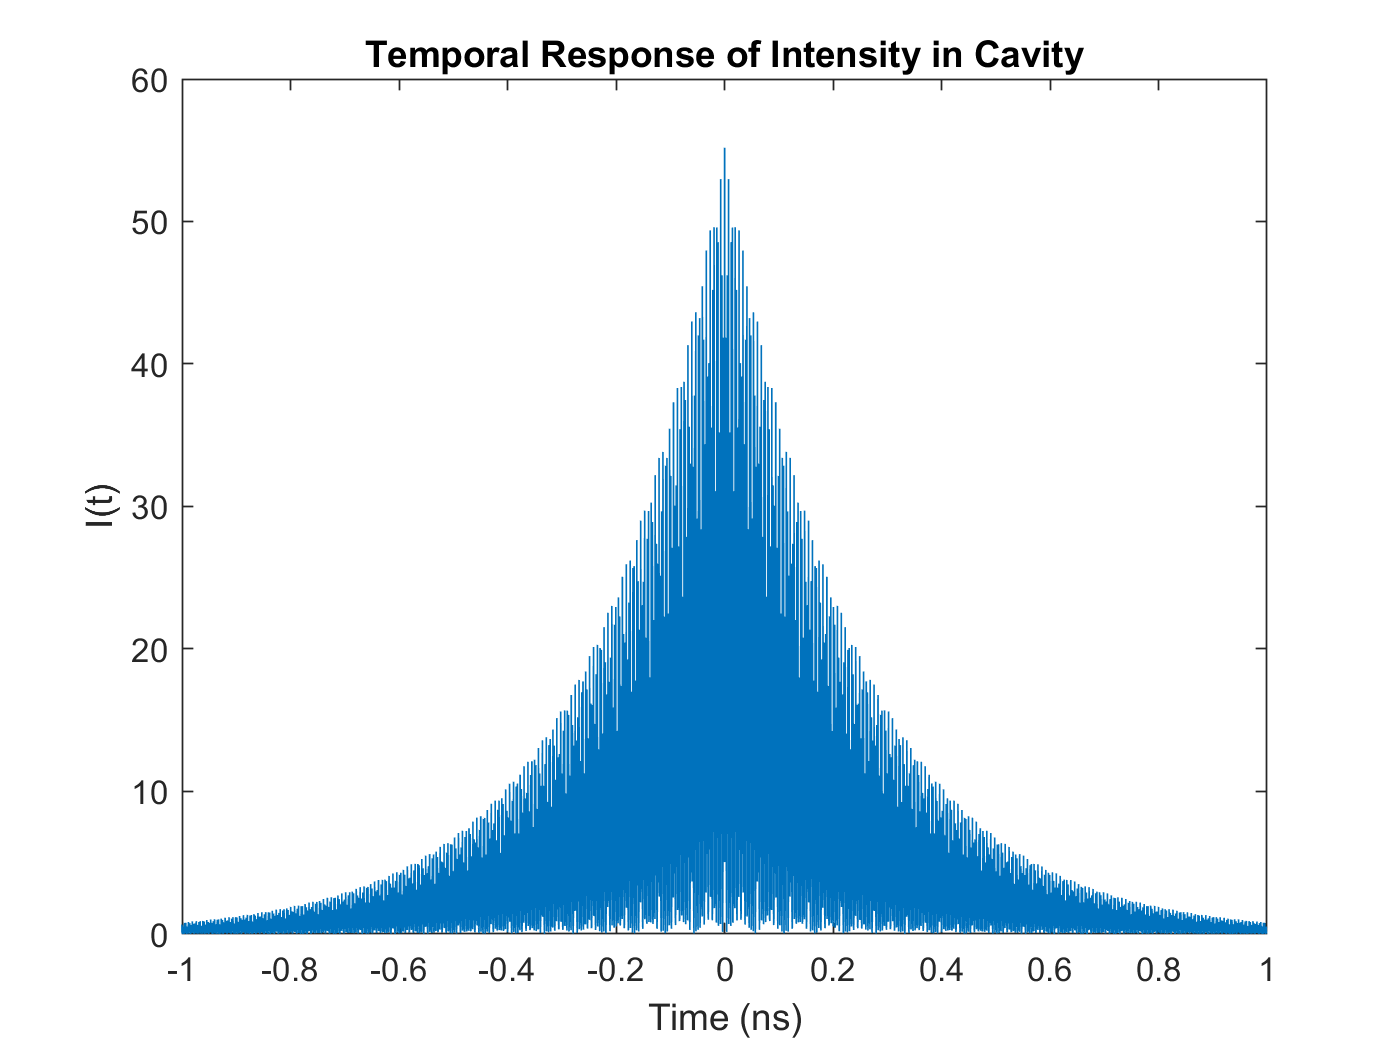

dlambda = 10^-13;
mid_lambda = 1510*10^-9;
df = (dlambda*c)/(1510*10^-9)^2;
f_sample = c/(min(lambda)) - c/(max(lambda));
fn  = -.5*f_sample:df:.5*f_sample; 
fn = fn + c/(mid_lambda);
t = -.5/df:1/f_sample:.5/df;
I_f = interp1(f,I,fn,'linear','extrap');
I_t = abs(ifftshift(ifft(I_f)));
plot(t*10^9,I_t);
xlim([-1,1])
xlabel('Time (ns)')
ylabel('I(t)')
title('Temporal Response of Intensity in Cavity')

*The cavity is identical to that of problem #1, the only difference being how we modeled the phase of the propagation inside the cavity.  Unless the values of $\beta$ are very large (increased by 10^5 or more), the phase has the same linear distribution.  The Intensity spectrum is unchanged for these smaller values of $\beta$.  Therefore, the same explanation can be given as in problem #1: The temporal response above demonstrates that the energy present in an optical cavity decays with time, which can be explained by mirror reflectivity.  The fact that R is .99, not 1.0, implies that 1% of the energy is lost every instance the path makes contact with the cavity.  Given the speeds at which photons are traveling in the cavity, the round trip time is small - consequently, the overall time necessary for the energy (thus intensity) in the cavity to decay to 0, effectively, is not long. 

**Part f)**

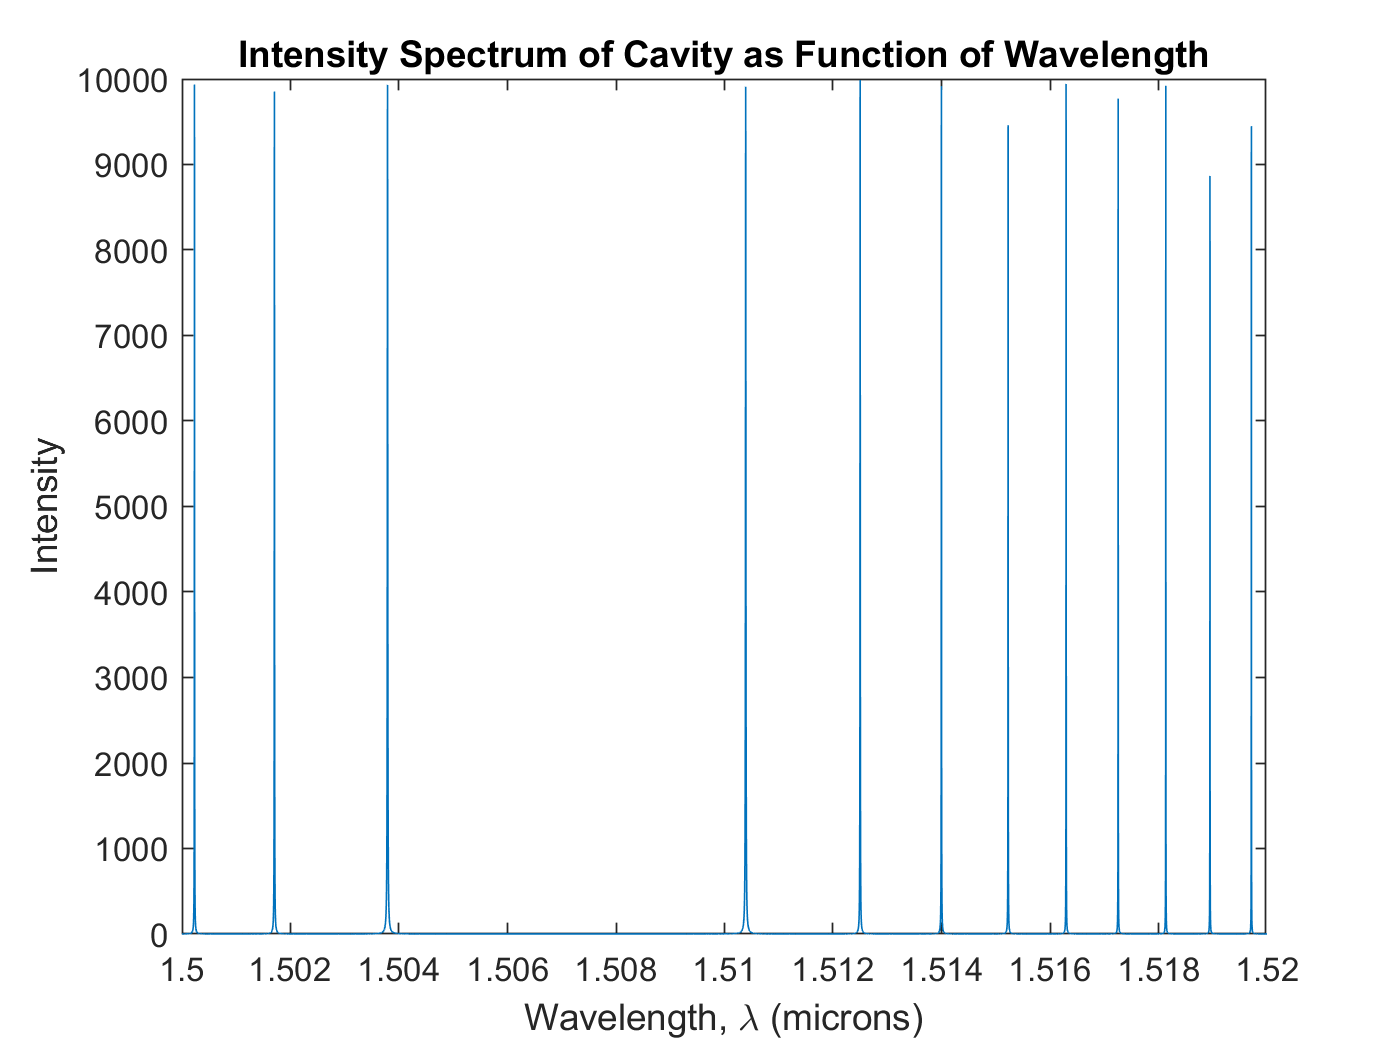

beta = beta_0 + beta_1*(2*pi*(f-f0)) + ((beta_2*10^5)/2)*(2*pi*(f-f0)).^2 + (beta_3/6)*(2*pi*(f-f0)).^3;
I = 1./((1-R).^2 + 4*R*(sin(beta*L)).^2);
plot(lambda*10^6,I)
xlabel('Wavelength, \lambda (microns)')
ylabel('Intensity')
title('Intensity Spectrum of Cavity as Function of Wavelength')

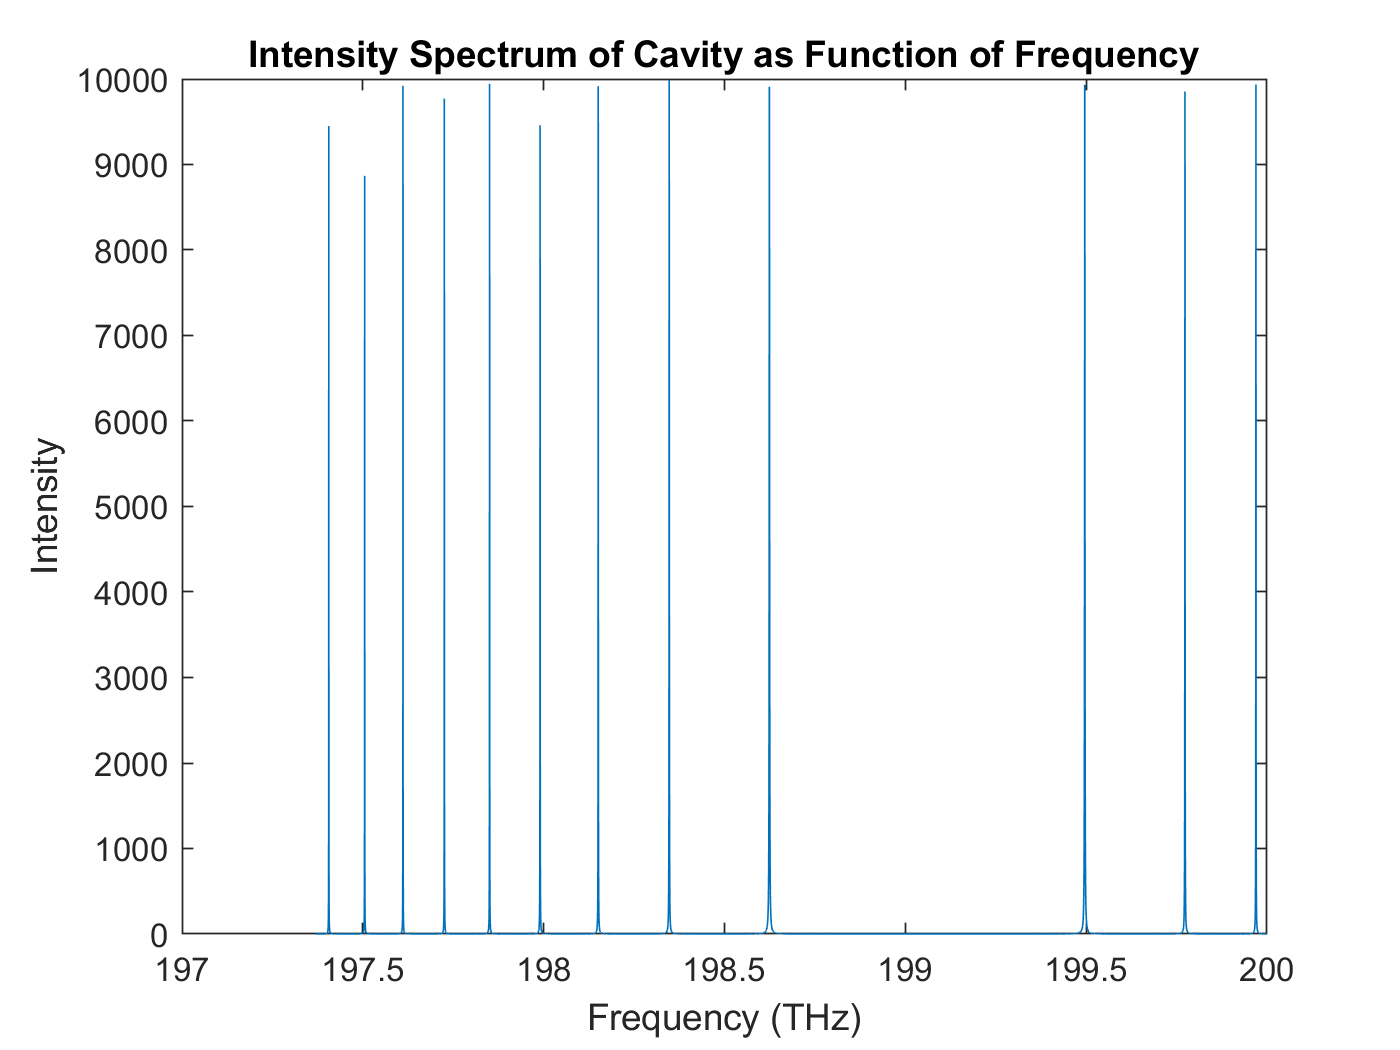

plot(f*10^-12,I)
xlabel('Frequency (THz)')
ylabel('Intensity')
title('Intensity Spectrum of Cavity as Function of Frequency')

*By increasing $\beta_2$, the phase takes on a quadratic shape centered at the lower wavelengths in the 1500 to 1520 nm spectrum.  Thus, more modes are present at higher wavelengths given this new phase position (meaning lower frequencies). 

**Part g)**

beta = beta_0 + beta_1*(2*pi*(f-f0)) + (beta_2/2)*(2*pi*(f-f0)).^2 + ((beta_3*10^7)/6)*(2*pi*(f-f0)).^3;
I = 1./((1-R).^2 + 4*R*(sin(beta*L)).^2)

I = 	1.0e+03 *

    0.0507    0.0407    0.0334    0.0279    0.0236    0.0203    0.0176    0.0154    0.0136    0.0121    0.0109    0.0098    0.0089    0.0081    0.0074    0.0068    0.0062    0.0058    0.0053    0.0050    0.0046    0.0043    0.0041    0.0038    0.0036    0.0034    0.0032    0.0030    0.0029    0.0027    0.0026    0.0025    0.0023    0.0022    0.0021    0.0020    0.0020    0.0019    0.0018    0.0017    0.0017    0.0016    0.0015    0.0015    0.0014    0.0014    0.0013    0.0013    0.0013    0.0012


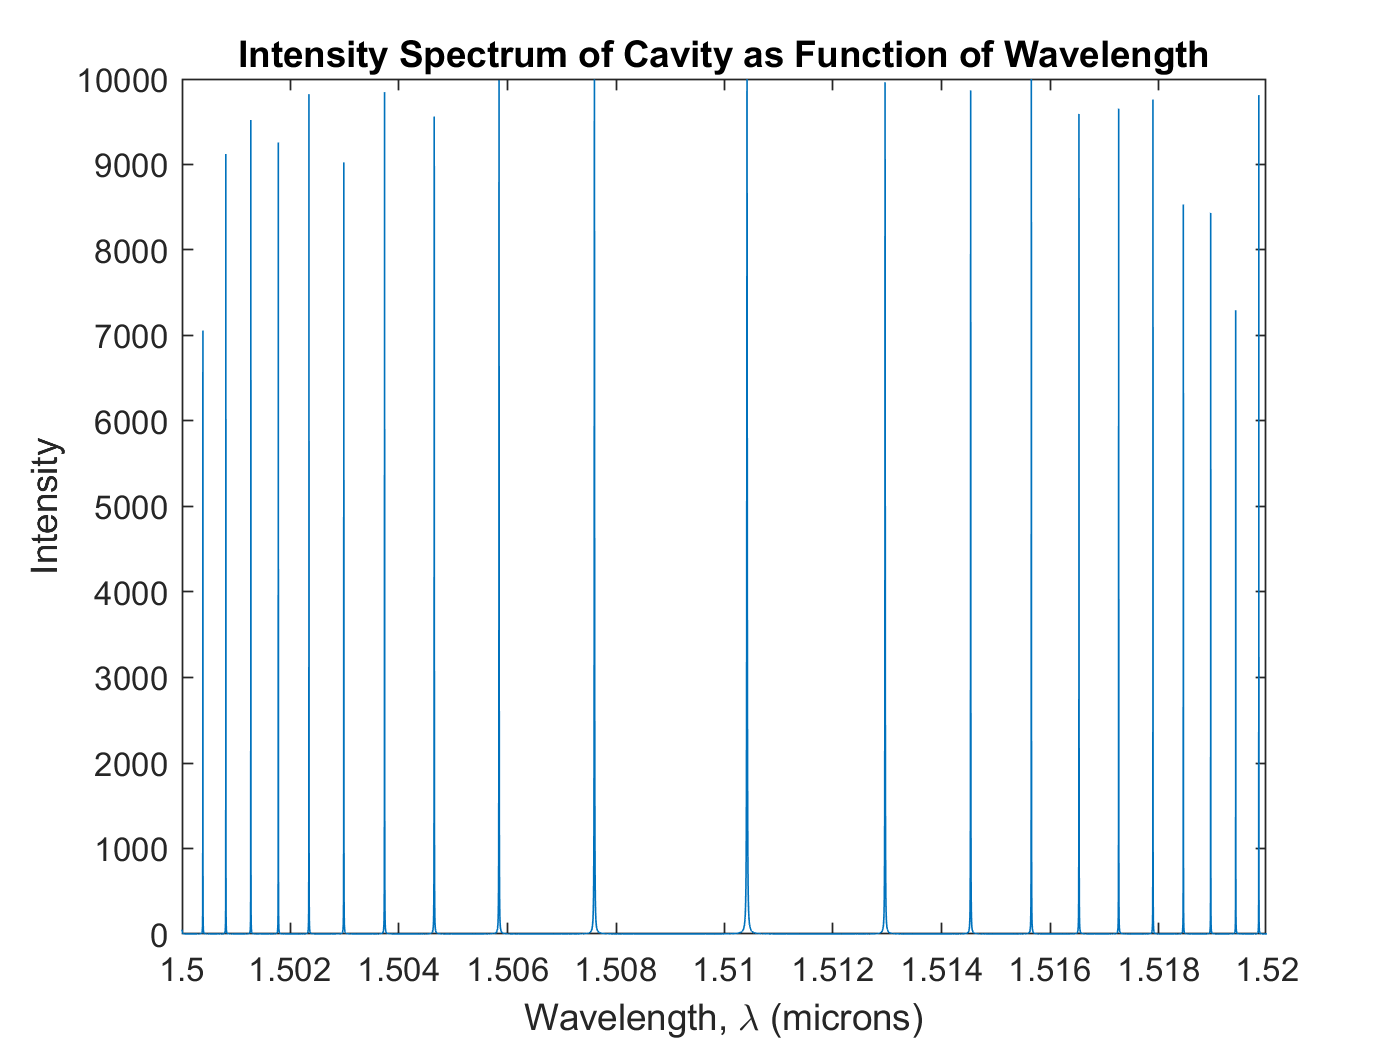

plot(lambda*10^6,I)
xlabel('Wavelength, \lambda (microns)')
ylabel('Intensity')
title('Intensity Spectrum of Cavity as Function of Wavelength')

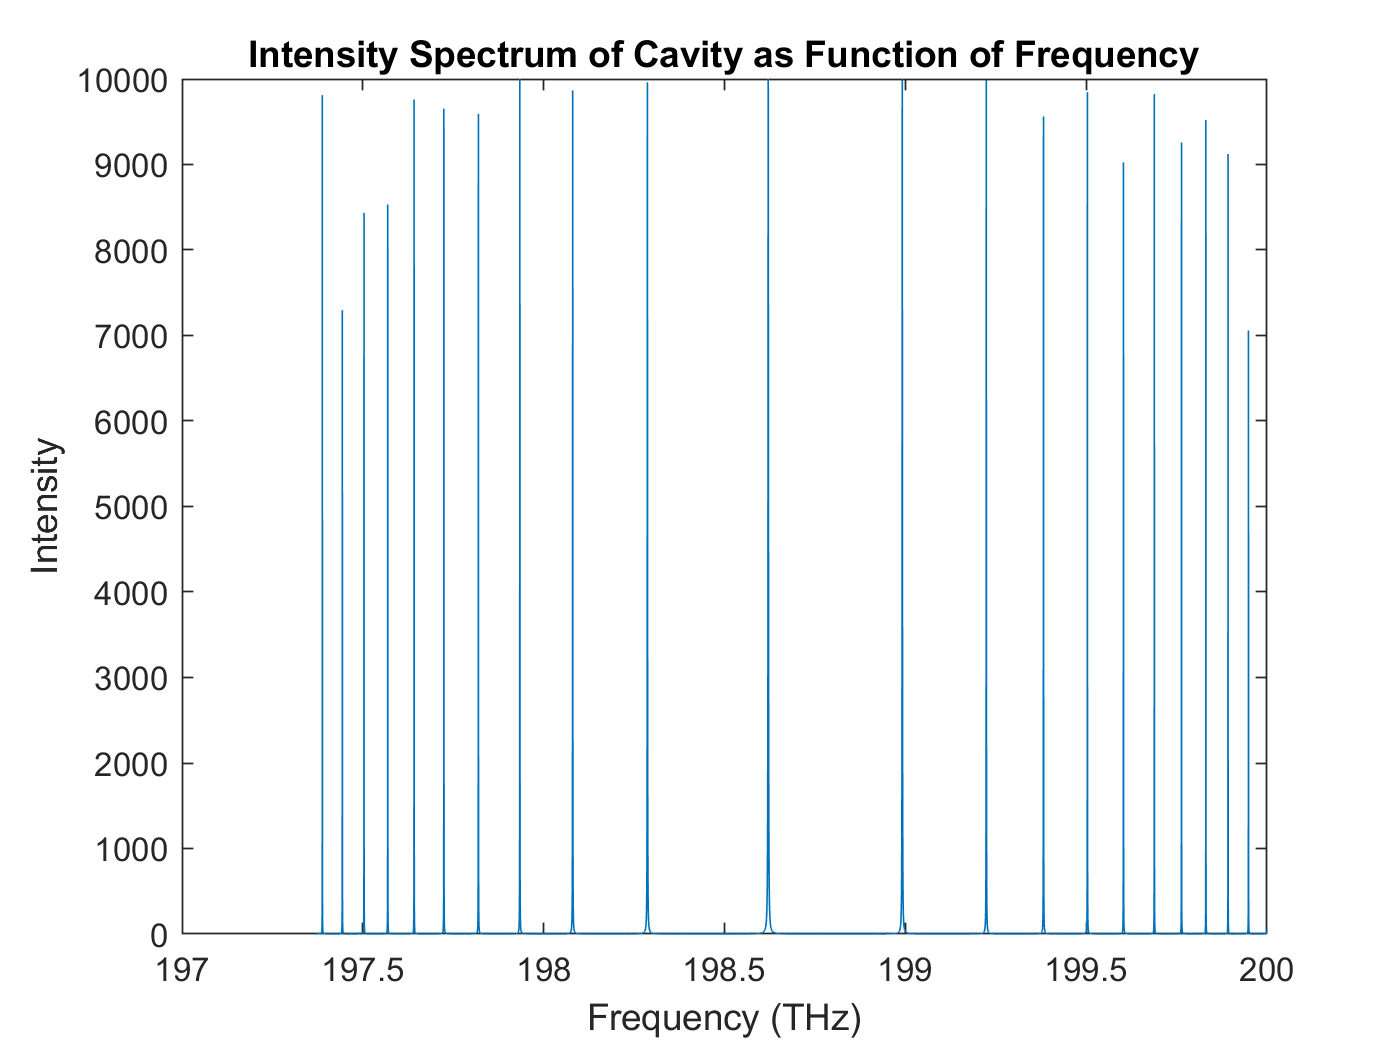

plot(f*10^-12,I)
xlabel('Frequency (THz)')
ylabel('Intensity')
title('Intensity Spectrum of Cavity as Function of Frequency')

*By increasing $\beta_3$, the phase takes on a cubic polynomial form, with the inflection point around the center wavelength/frequency.  The phase is stronger at lower and higher wavelengths, but not at points around the center wavelength.  Consequently, the intensity spikes are less frequent around the center and 'packed together' on both ends of the spectrum. 